# Air Compressor Data Classification

# Part 1: Data Preparation

Copyright 2020 The MathWorks, Inc.

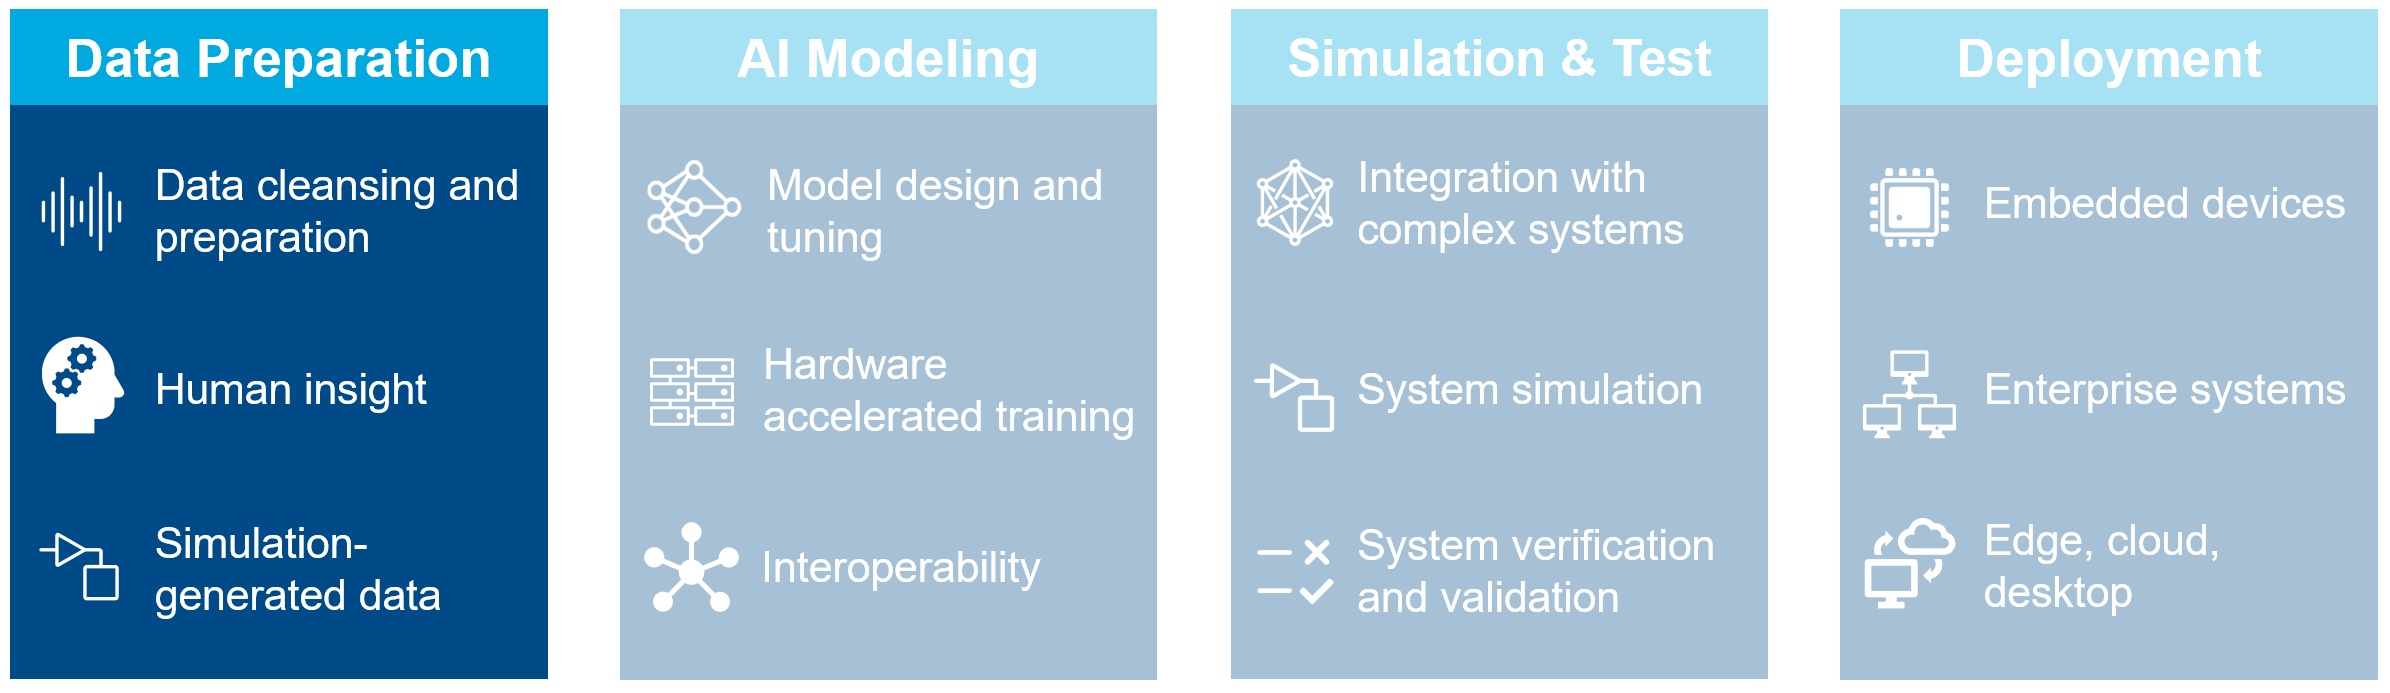

## Configuration

Click on the checkboxes below to choose options for how to run this script.

doFeatureExtraction = true; % if unchecked, this will save time by loading previous results

Make sure we run this as a project.

try
    prj = currentProject;
catch
    open("Aircompressorclassification.prj");
    OpenPart1;
    prj = currentProject;
end

## Create Datastore

The Air Compressor Health State dataset should be first [downloaded](http://www.iitk.ac.in/idea/datasets/) and unzipped into a local subdirectory called AirCompressorData. 

The recorded data is sorted by subfolder. Each subfolder contains over 200 recordings of the labeled state. 

We create our datastore by providing the input data folder and specifying that the source of the labels is the name of the subfolders. 

dataFolder = 'AirCompressorDataset';
ads = audioDatastore(dataFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

We then reset the random number generator (for consistent results) and shuffle the data.

rng(3);
ads = shuffle(ads);

## Split Into Training and Validation Sets

Split the data into training and validation by doing a 90% training, 10% validation split. The `countEachLabel` command will show us how many samples of data belong to each category in the dataset.

[adsTrain,adsValidation] = splitEachLabel(ads,0.9,0.1);
countEachLabel(adsTrain)

ans = 8×2 table
      Label      Count
    _________    _____

    Bearing       203 
    Flywheel      203 
    Healthy       203 
    LIV           203 
    LOV           203 
    NRV           203 
    Piston        203 
    Riderbelt     203 


countEachLabel(adsValidation)

ans = 8×2 table
      Label      Count
    _________    _____

    Bearing       22  
    Flywheel      22  
    Healthy       22  
    LIV           22  
    LOV           22  
    NRV           22  
    Piston        22  
    Riderbelt     22  


## Data Preparation

### Human Insight

The data we are working with are time-series recordings of acoustics from different parts of an air compressor. As such, there are strong relationships between samples in time.

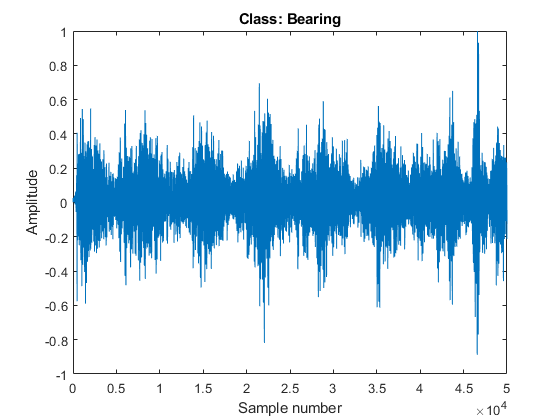

sampleData = read(adsTrain);
sampleDataCategory = adsTrain.Labels(1);
plot(1:numel(sampleData), sampleData);
xlabel("Sample number");
ylabel("Amplitude");
title("Class: " + string(sampleDataCategory));

Listen to a sample of the audio if desired.

% sound(sampleData,16000);

Because of this, we should be able to use a type of recurrent neural network (RNN) as a model for the data. The type of RNN we will eventually select is a bi-directional long short term memory (LSTM) network. However, before we can get to modeling, it's important to prepare the data adequately. Oftentimes, it is best to transform or extract features from 1-dimensional signal data in order to increase a model's representative power, as we see in the diagram below:

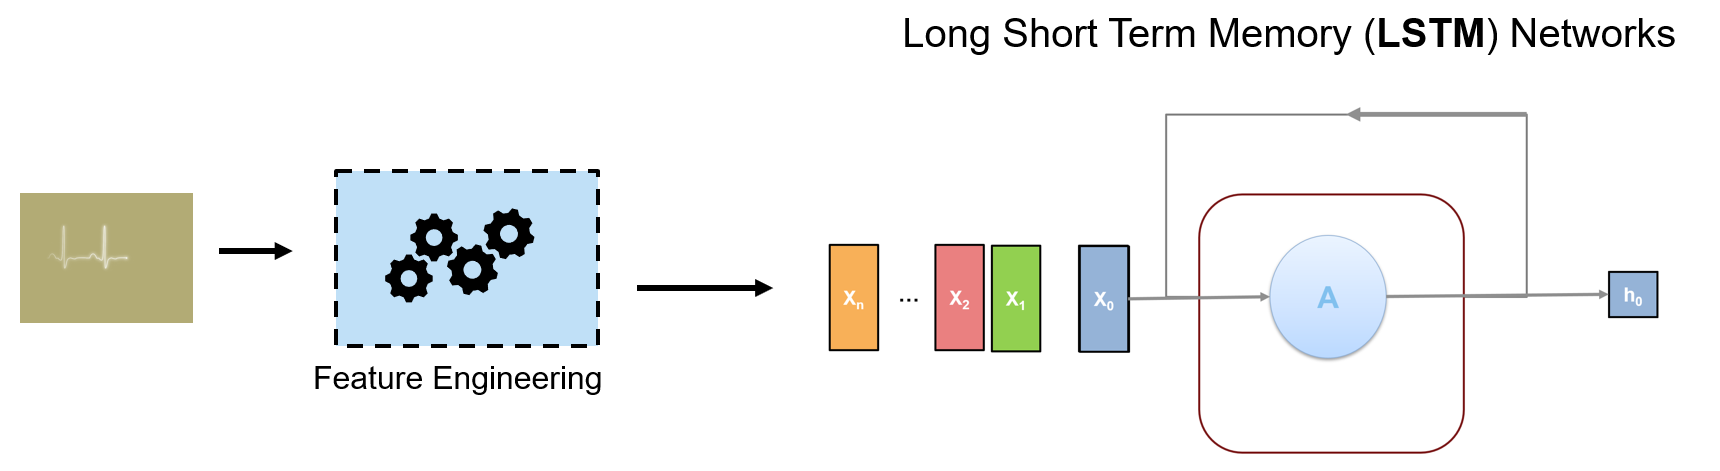

In this part of the workflow, we will focus on how to engineer features from the original data that will aid in the model's ability to classify the inputs.

## Generate Training Features

The next step is to extract the set of acoustic features that will be used as inputs to the network. 

The Audio Toolbox provides a set of Spectral Descriptor features that are commonly used as inputs to deep learning networks.

We can extract the features with individual functions, or we can simplify the workflow and use a single object called audioFeatureExtractor to do it all at once. 

trainingFeatures = cell(1,numel(adsTrain.Files));
windowLength = 512;
overlapLength = 0;

aFE = audioFeatureExtractor('SampleRate',16e3, ...
    'Window',hamming(windowLength,'periodic'),...
    'OverlapLength',overlapLength,...
    'spectralCentroid',true, ...
    'spectralCrest',true, ...
    'spectralDecrease',true, ...
    'spectralEntropy',true,...
    'spectralFlatness',true,...
    'spectralFlux',false,...                
    'spectralKurtosis',true,...
    'spectralRolloffPoint',true,...
    'spectralSkewness',true,...
    'spectralSlope',true,...
    'spectralSpread',true);

if doFeatureExtraction
    reset(adsTrain);
    index = 1;
    tic;
    while hasdata(adsTrain)
        data = read(adsTrain);
        trainingFeatures{index} = extract(aFE,data);
        index = index + 1;
    end
    fprintf('Extraction took %f seconds.\n',toc);
else
    load("TrainingFeatures.mat"); 
    disp("Training data features loaded.")
end

Extraction took 11.177660 seconds.


## Normalize Training Features

Networks will often train better when normalized. Calculate the mean and standard deviation and normalize each element of the training feature set. 

allTrainingFeatures = cat(1,trainingFeatures{:});
M = mean(allTrainingFeatures);
S = std(allTrainingFeatures);

for index = 1:numel(adsTrain.Files)
   trainingFeatures{index} =  ((trainingFeatures{index} - M)./S).';
end

## Generate and Normalize Validation Features

Repeat the feature extraction for the validation features. Perform the normalization inside the loop.

validationFeatures = cell(1,numel(adsValidation.Files));

if doFeatureExtraction
    index = 1;
    tic;
    while hasdata(adsValidation)
       data = read(adsValidation);
       validationFeatures{index} = extract(aFE,data);
       validationFeatures{index} = ((validationFeatures{index}  - M) ./ S).';
       index = index + 1;
    end
    fprintf('Validation Extraction took %f seconds.\n',toc);
else
    load("ValidationFeatures.mat"); %#ok<*UNRCH> 
end

Validation Extraction took 1.210202 seconds.


## Generate MATLAB function compatible with C/C++ Code Generation

We want to eventually deploy our deep learning algorithm to an embedded target. That means we also need to deploy the code used to perform the feature extraction. 

Fortunately, we can take advantage of a capability of the audioFeatureExtractor to generate a MATLAB function compatible with C/C++ code generation. This function will be used in step 3 when we are ready to generate code and deploy the entire system.

filename = fullfile(pwd,"HelperFiles","extractFeatures");
generateMATLABFunction(aFE,filename,'IsStreaming',true);